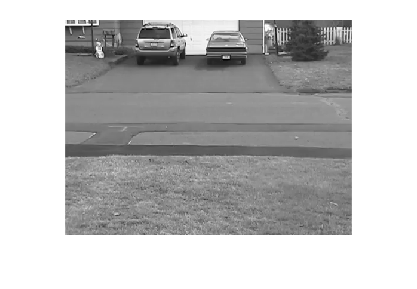

clear
clc

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%            TAKE CARE! THIS FILE IS JUST FOR ILLUSTRATION           %
%            AND IT DOES NOT CONSTRUCT THE RECIEVED VIDEO            %
%            IT JUST SHOW THE TWO STEPS OF ENCODING AND              %
%            DECODING FOR TWO FRAME AND SHOW ALL STEPS               %
%            BEHIND THE SENE                                         %
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

video  = VideoReader("Trial.mp4");

Frames_Number = video.NumFrames;
Video_Duration = video.Duration; %---> one reference frame for each second
framesPerSec = video.FrameRate;

% Reference frame
frame1 = get_frame(video,1);
imshow(frame1)

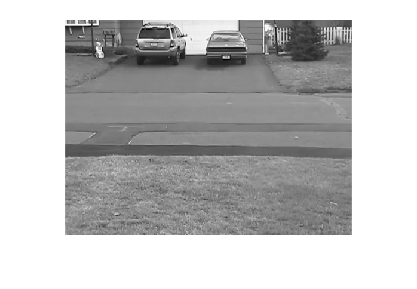



frame2 = get_frame(video,2);
imshow(frame2)



%Dividing the current frame into 8*8 blocks
[r2,c2] = size(frame2) %360*480

r2 = 360

c2 = 480

rows = 8*ones(1,r2/8);
columns = 8*ones(1,c2/8);

ImBlocks = mat2cell(double(frame2),rows,columns)

ImBlocks = 45×60 cell array
    {8×8 double}    {8×8 double}    {8×8 double}    {8×8 double}    {8×8 double}    {8×8 double}    {8×8 double}    {8×8 double}    {8×8 double}    {8×8 double}    {8×8 double}    {8×8 double}    {8×8 double}    {8×8 double}    {8×8 double}    {8×8 double}    {8×8 double}    {8×8 double}    {8×8 double}    {8×8 double}    {8×8 double}    {8×8 double}    {8×8 double}    {8×8 double}    {8×8 double}    {8×8 double}    {8×8 double}    {8×8 double}    {8×8 double}    {8×8 double}    {8×8 double}    {8×8 double}    {8×8 double}    {8×8 double}    {8×8 double}    {8×8 double}    {8×8 double}    {8×8 double}    {8×8 double}    {8×8 double}    {8×8 double}    {8×8 double}    {8×8 double}    {8×8 double}    {8×8 double}    {8×8 double}    {8×8 double}    {8×8 double}    {8×8 double}    {8×8 double}    {8×8 double}    {8×8 double}    {8×8 double}    {8×8 double}    {8×8 double}    {8×8 double}    {8×8 double}    {8×8 double}    {8×8 double}    {8×8 double}
    {8×8 do

[rowB,columnB]= size(ImBlocks);

## Matching each macroblock in the current frame with the reference frame

difference_matrix = ImBlocks;
difference_i = zeros(1,length(ImBlocks(:,1)) * length(ImBlocks(1,:)));
difference_j = zeros(1,length(ImBlocks(:,1)) * length(ImBlocks(1,:)));
index = 1;

%motion vector 
motion_vector = cell(length(ImBlocks(:,1)),length(ImBlocks(1,:)));
motion_vector(:,:) = {zeros(8)};
%

for r = 1: length(ImBlocks(:,1))
    for c = 1: length(ImBlocks(1,:))
        Macro_block = cell2mat(ImBlocks(r,c));

        %search region
        current_i_start = 8*r - 7;
        current_j_start = 8*c - 7;
        MacroBlock_size = length(Macro_block(1,:));
        Ref_frame_size = size(frame1);
        [i_start,j_start ,i_final,j_final] = searchRegion(current_i_start,current_j_start,MacroBlock_size,Ref_frame_size);
        
        %Matching blocks
        search_Area = [i_start,j_start ,i_final,j_final];
        [i_diff,j_diff ,diff_Macro_Block] = MatchingBlocks(Macro_block,frame1,search_Area,current_i_start,current_j_start);
        
        difference_i(index) = i_diff;
        difference_j(index) = j_diff;
        difference_matrix(r,c) = num2cell(diff_Macro_Block,[1 2]);
        
        %motion vector
        cell = zeros(8);
        cell(1,1) = i_diff;
        cell(1,2) = j_diff;
        motion_vector(r,c) = num2cell(cell,[1 2]);
        index = index + 1;
    end
end

# JPEG part

ImBlocks = 45×60 cell array
    {8×8 double}    {8×8 double}    {8×8 double}    {8×8 double}    {8×8 double}    {8×8 double}    {8×8 double}    {8×8 double}    {8×8 double}    {8×8 double}    {8×8 double}    {8×8 double}    {8×8 double}    {8×8 double}    {8×8 double}    {8×8 double}    {8×8 double}    {8×8 double}    {8×8 double}    {8×8 double}    {8×8 double}    {8×8 double}    {8×8 double}    {8×8 double}    {8×8 double}    {8×8 double}    {8×8 double}    {8×8 double}    {8×8 double}    {8×8 double}    {8×8 double}    {8×8 double}    {8×8 double}    {8×8 double}    {8×8 double}    {8×8 double}    {8×8 double}    {8×8 double}    {8×8 double}    {8×8 double}    {8×8 double}    {8×8 double}    {8×8 double}    {8×8 double}    {8×8 double}    {8×8 double}    {8×8 double}    {8×8 double}    {8×8 double}    {8×8 double}    {8×8 double}    {8×8 double}    {8×8 double}    {8×8 double}    {8×8 double}    {8×8 double}    {8×8 double}    {8×8 double}    {8×8 double}    {8×8 double}
    {8×8 do

Quantization table 1


Q1 =      1     1     1     1     1     2     2     4
     1     1     1     1     1     2     2     4
     1     1     1     1     2     2     2     4
     1     1     1     1     2     2     4     8
     1     1     2     2     2     2     4     8
     2     2     2     2     2     4     8     8
     2     2     2     4     4     8     8    16
     4     4     4     4     8     8    16    16


Run length code 1


RLs1 =    174    48   -41    25    22    39   -10    21   -17   -14     4     7   -14    -3   -24    -2   -10     6     7    -4     0     1    -1     1    -1    -3     5    -2     6     1     4     0     1    -3     0     1    -1     0     3     1     1     0     2    -2     0     1     1     4     0     1


Compressed picture 1


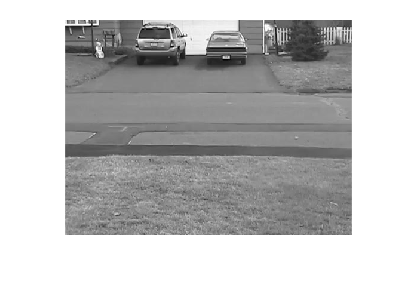

Compression Ratio:


compression1 = 1.4770

Recieved_Ref_Frame = JPEG(frame1,1);


%current frame diferrence
J_PEG_Input = uint8(cell2mat(difference_matrix))

J_PEG_Input = 360×480 uint8 matrix
    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    6    6
    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    5    6
    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    6    5
    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0  

ImBlocks = 45×60 cell array
    {8×8 double}    {8×8 double}    {8×8 double}    {8×8 double}    {8×8 double}    {8×8 double}    {8×8 double}    {8×8 double}    {8×8 double}    {8×8 double}    {8×8 double}    {8×8 double}    {8×8 double}    {8×8 double}    {8×8 double}    {8×8 double}    {8×8 double}    {8×8 double}    {8×8 double}    {8×8 double}    {8×8 double}    {8×8 double}    {8×8 double}    {8×8 double}    {8×8 double}    {8×8 double}    {8×8 double}    {8×8 double}    {8×8 double}    {8×8 double}    {8×8 double}    {8×8 double}    {8×8 double}    {8×8 double}    {8×8 double}    {8×8 double}    {8×8 double}    {8×8 double}    {8×8 double}    {8×8 double}    {8×8 double}    {8×8 double}    {8×8 double}    {8×8 double}    {8×8 double}    {8×8 double}    {8×8 double}    {8×8 double}    {8×8 double}    {8×8 double}    {8×8 double}    {8×8 double}    {8×8 double}    {8×8 double}    {8×8 double}    {8×8 double}    {8×8 double}    {8×8 double}    {8×8 double}    {8×8 double}
    {8×8 do

Quantization table 1


Q1 =      1     1     1     1     1     2     2     4
     1     1     1     1     1     2     2     4
     1     1     1     1     2     2     2     4
     1     1     1     1     2     2     4     8
     1     1     2     2     2     2     4     8
     2     2     2     2     2     4     8     8
     2     2     2     4     4     8     8    16
     4     4     4     4     8     8    16    16


Run length code 1


RLs1 =      0    64     0    64     0    64     0    64     0    64     0    64     2     2     1     0     1     2     0     1    -1     0     1     1    -1     0     1    -1     0     1    -1     0     5     1     0    44     0    64     0    64     0    64     0    64     0    64     0    64     0    64


Compressed picture 1


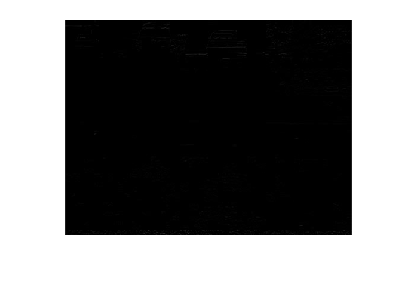

Compression Ratio:


compression1 = 8.9274

Recieved_diff_frame = JPEG(J_PEG_Input,1);


%Current frame motion vector
J_PEG_Input = uint8(cell2mat(motion_vector))

J_PEG_Input = 360×480 uint8 matrix
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0 

ImBlocks = 45×60 cell array
    {8×8 double}    {8×8 double}    {8×8 double}    {8×8 double}    {8×8 double}    {8×8 double}    {8×8 double}    {8×8 double}    {8×8 double}    {8×8 double}    {8×8 double}    {8×8 double}    {8×8 double}    {8×8 double}    {8×8 double}    {8×8 double}    {8×8 double}    {8×8 double}    {8×8 double}    {8×8 double}    {8×8 double}    {8×8 double}    {8×8 double}    {8×8 double}    {8×8 double}    {8×8 double}    {8×8 double}    {8×8 double}    {8×8 double}    {8×8 double}    {8×8 double}    {8×8 double}    {8×8 double}    {8×8 double}    {8×8 double}    {8×8 double}    {8×8 double}    {8×8 double}    {8×8 double}    {8×8 double}    {8×8 double}    {8×8 double}    {8×8 double}    {8×8 double}    {8×8 double}    {8×8 double}    {8×8 double}    {8×8 double}    {8×8 double}    {8×8 double}    {8×8 double}    {8×8 double}    {8×8 double}    {8×8 double}    {8×8 double}    {8×8 double}    {8×8 double}    {8×8 double}    {8×8 double}    {8×8 double}
    {8×8 do

Quantization table 1


Q1 =      1     1     1     1     1     2     2     4
     1     1     1     1     1     2     2     4
     1     1     1     1     2     2     2     4
     1     1     1     1     2     2     4     8
     1     1     2     2     2     2     4     8
     2     2     2     2     2     4     8     8
     2     2     2     4     4     8     8    16
     4     4     4     4     8     8    16    16


Run length code 1


RLs1 =      0    64     0    64     0    64     0    64     0    64     0    64     0    64     0    64     0    64     0    64     0    64     0    64     0    64     0    64     0    64     0    64     0    64     0    64     0    64     0    64     0    64     0    64     0    64     0    64     0    64


Compressed picture 1


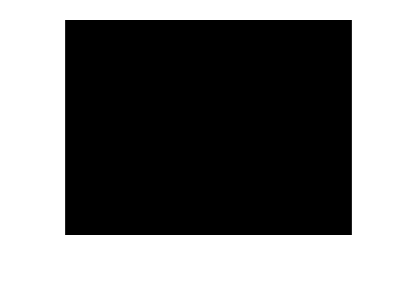

Compression Ratio:


compression1 = 97.0904

Recieved_motion_vector = JPEG(J_PEG_Input,1);



[r2,c2] = size(Recieved_diff_frame) %360*480

r2 = 360

c2 = 480

rows = 8*ones(1,r2/8);
columns = 8*ones(1,c2/8);
Recieved_diff_frame = mat2cell(double(Recieved_diff_frame),rows,columns)

Recieved_diff_frame = 45×60 cell array
    {8×8 double}    {8×8 double}    {8×8 double}    {8×8 double}    {8×8 double}    {8×8 double}    {8×8 double}    {8×8 double}    {8×8 double}    {8×8 double}    {8×8 double}    {8×8 double}    {8×8 double}    {8×8 double}    {8×8 double}    {8×8 double}    {8×8 double}    {8×8 double}    {8×8 double}    {8×8 double}    {8×8 double}    {8×8 double}    {8×8 double}    {8×8 double}    {8×8 double}    {8×8 double}    {8×8 double}    {8×8 double}    {8×8 double}    {8×8 double}    {8×8 double}    {8×8 double}    {8×8 double}    {8×8 double}    {8×8 double}    {8×8 double}    {8×8 double}    {8×8 double}    {8×8 double}    {8×8 double}    {8×8 double}    {8×8 double}    {8×8 double}    {8×8 double}    {8×8 double}    {8×8 double}    {8×8 double}    {8×8 double}    {8×8 double}    {8×8 double}    {8×8 double}    {8×8 double}    {8×8 double}    {8×8 double}    {8×8 double}    {8×8 double}    {8×8 double}    {8×8 double}    {8×8 double}    {8×8 double}


Recieved_motion_vector = mat2cell(double(Recieved_motion_vector),rows,columns)

Recieved_motion_vector = 45×60 cell array
    {8×8 double}    {8×8 double}    {8×8 double}    {8×8 double}    {8×8 double}    {8×8 double}    {8×8 double}    {8×8 double}    {8×8 double}    {8×8 double}    {8×8 double}    {8×8 double}    {8×8 double}    {8×8 double}    {8×8 double}    {8×8 double}    {8×8 double}    {8×8 double}    {8×8 double}    {8×8 double}    {8×8 double}    {8×8 double}    {8×8 double}    {8×8 double}    {8×8 double}    {8×8 double}    {8×8 double}    {8×8 double}    {8×8 double}    {8×8 double}    {8×8 double}    {8×8 double}    {8×8 double}    {8×8 double}    {8×8 double}    {8×8 double}    {8×8 double}    {8×8 double}    {8×8 double}    {8×8 double}    {8×8 double}    {8×8 double}    {8×8 double}    {8×8 double}    {8×8 double}    {8×8 double}    {8×8 double}    {8×8 double}    {8×8 double}    {8×8 double}    {8×8 double}    {8×8 double}    {8×8 double}    {8×8 double}    {8×8 double}    {8×8 double}    {8×8 double}    {8×8 double}    {8×8 double}    {8×8 doubl

# Reconstructing the frame

%recieved:
%reference frame
%difference_matrix
%motion vector:
%difference_i,difference_j

RecievedImage = Recieved_diff_frame;
blockSize = 8;
index = 1;
for r = 1: length(RecievedImage(:,1))
    for c = 1: length(RecievedImage(1,:))
        temp = cell2mat(Recieved_motion_vector(1,1));
        difference_i = temp(1,1);
        difference_j = temp(1,2);
        Ref_frame_block = RefBlock(r,c,difference_i,difference_j,blockSize,Recieved_Ref_Frame);
        RecievedImage(r,c) = num2cell((Ref_frame_block + cell2mat(RecievedImage(r,c))),[1 2]);
    end
end
Recieved_frame = uint8(cell2mat(RecievedImage))

Recieved_frame = 360×480 uint8 matrix
   225   228   206    79    68   121   117   134   149   129   120   141   122    96   115   120   147   233   228   247   238   115   111   155   141   137   131   128   128   128   127   126    63    47   149   244   237   251   236   134    75   120   156    93    56    95   151   163   152   142
   231   231   213    86    70   121   118   141   161   139   122   135   127   108   118   119   151   233   229   246   237   120   116   159   148   143   137   133   132   133   133   132    83    40   135   246   243   255   241   130    77   113   149   100    65    93   145   162   159   140
   237   232   214    85    67   119   115   136   167   144   125   135   138   125   120   113   154   229   229   248   243   127   120   168   152   147   141   137   136   137   137   137   121    49   128   243   229   236   243   146    78    99   124    98    75    87   126   153   150   136
   232   237   224    92    69   124   122   134   177   14


figure
title('frame before sending')
imshow(frame2)

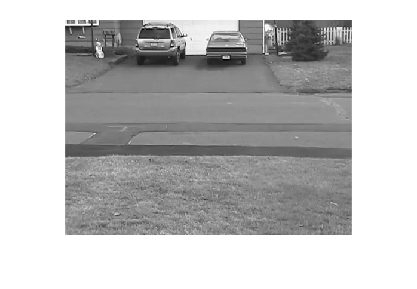


figure
title('frame after recieving')
imshow(Recieved_frame)